**Skills 6: Chain of Water Bodies Using Cells-In-Series Model**

**1.)**

**Given**

- $n$ ranges from 1 to 1000

- $Q_t /V_t$ ranges from 0 to 5

**Required**

- Make several plots of ${\textrm{CV}}_t /m$ vs $Q_t V_t$

**Sketch**

**Theory**

- This problem will use a cells-in-series model where $C_n =C_o *{\left(1+\frac{kV_t }{Q}\right)}^{-n}$

**Assumptions**

- 
$$C_0 =10\;\textrm{mg}/m^3$$


- 
$$V_t =1*{10}^{50} \;m^3$$


- 
$$k=0\ldotp 1/\textrm{day}*\frac{1\;\textrm{day}}{86400\;s}=1\ldotp 16*{10}^{-6} /s$$


- 
$$\textrm{Qt}=1*{10}^{50} \;m^3 /\textrm{day}$$


- 
$$M=1*{10}^{51} \;\textrm{mg}$$


**Solution**

Input variables (changed for each plot):

- I would put the code at the end, but I had to include it here to generate each plot

n = [1, 250, 500, 750, 1000];
KVtQ = 0;
QtVt = [1, 2, 3, 4, 5];
Vt = 1e50;
M= 1e51;

C1 = 10*((1+KVtQ)^1) %n=1

C1 = 10

C2 = 10*((1+KVtQ)^250);
C3 = 10*((1+KVtQ)^500);
C4 = 10*((1+KVtQ)^750);
C5 = 10*((1+KVtQ)^1000);

CtVtM = [(C1*Vt)/M, (C2*Vt)/M, (C3*Vt)/M, (C4*Vt)/M, (C5*Vt)/M];

- 
$$KV_t Q=0$$


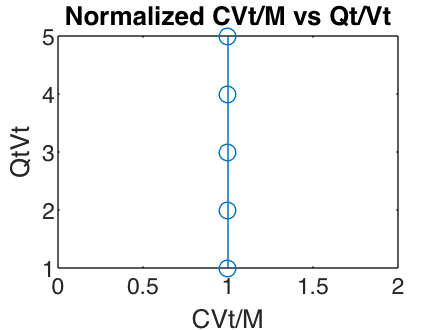

figure
plot(CtVtM,QtVt, 'o-')

title(["Normalized CVt/M vs Qt/Vt"])
xlabel("CVt/M")
ylabel("QtVt")

- 
$$KV_t Q=0\ldotp 5$$


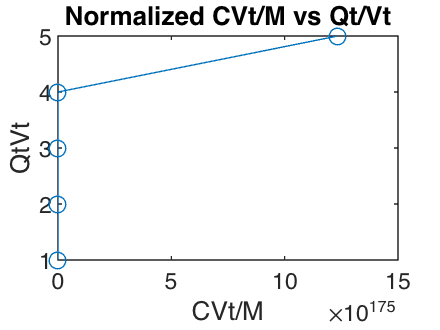

n = [1, 250, 500, 750, 1000];
KVtQ = 0.5;
QtVt = [1, 2, 3, 4, 5];
Vt = 1e50;
M= 1e51;

C1 = 10*((1+KVtQ)^1); %n=1
C2 = 10*((1+KVtQ)^250);
C3 = 10*((1+KVtQ)^500);
C4 = 10*((1+KVtQ)^750);
C5 = 10*((1+KVtQ)^1000);

CtVtM = [(C1*Vt)/M, (C2*Vt)/M, (C3*Vt)/M, (C4*Vt)/M, (C5*Vt)/M];
figure
plot(CtVtM,QtVt, 'o-')

title(["Normalized CVt/M vs Qt/Vt"])
xlabel("CVt/M")
ylabel("QtVt")

- 
$$KV_t Q=1$$


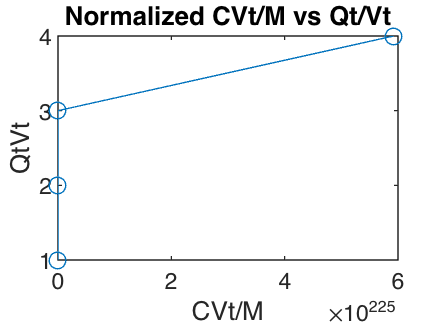

n = [1, 250, 500, 750, 1000];
KVtQ = 1;
QtVt = [1, 2, 3, 4, 5];
Vt = 1e50;
M= 1e51;

C1 = 10*((1+KVtQ)^1); %n=1
C2 = 10*((1+KVtQ)^250);
C3 = 10*((1+KVtQ)^500);
C4 = 10*((1+KVtQ)^750);
C5 = 10*((1+KVtQ)^1000);

CtVtM = [(C1*Vt)/M, (C2*Vt)/M, (C3*Vt)/M, (C4*Vt)/M, (C5*Vt)/M];
figure
plot(CtVtM,QtVt, 'o-')

title(["Normalized CVt/M vs Qt/Vt"])
xlabel("CVt/M")
ylabel("QtVt")

- 
$$KV_t Q=1$$


n = [1, 250, 500, 750, 1000];
KVtQ = 1;
QtVt = [1, 2, 3, 4, 5];
Vt = 1e50;
M= 1e51;

C1 = 10*((1+KVtQ)^1); %n=1
C2 = 10*((1+KVtQ)^250);
C3 = 10*((1+KVtQ)^500);
C4 = 10*((1+KVtQ)^750);
C5 = 10*((1+KVtQ)^1000);

CtVtM = [(C1*Vt)/M, (C2*Vt)/M, (C3*Vt)/M, (C4*Vt)/M, (C5*Vt)/M];
figure
plot(CtVtM,QtVt, 'o-')

title(["Normalized CVt/M vs Qt/Vt"])
xlabel("CVt/M")
ylabel("QtVt")

- 
$$KV_t Q=5$$


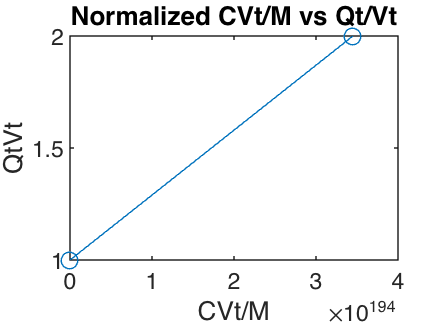

n = [1, 250, 500, 750, 1000];
KVtQ = 5;
QtVt = [1, 2, 3, 4, 5];
Vt = 1e50;
M= 1e51;

C1 = 10*((1+KVtQ)^1); %n=1
C2 = 10*((1+KVtQ)^250);
C3 = 10*((1+KVtQ)^500);
C4 = 10*((1+KVtQ)^750);
C5 = 10*((1+KVtQ)^1000);

CtVtM = [(C1*Vt)/M, (C2*Vt)/M, (C3*Vt)/M, (C4*Vt)/M, (C5*Vt)/M];
figure
plot(CtVtM,QtVt, 'o-')

title(["Normalized CVt/M vs Qt/Vt"])
xlabel("CVt/M")
ylabel("QtVt")

**Discussion**

- Varying $n\;\textrm{and}\;kV_t /Q$ appears to have a large effect on concentration profiles, particuarly when $kV_t /Q$ is 1 or greater since the concentration is infinitely large at that point. The major implication for computer modeling is that the model is very sensitive to changes in the input varibablesand if they are not measured/estimated correctly, then the model will be way off.   

**...................................................................................................................................................................................................**

**12.)**

**Given:**

- discharge ($w$) = $1000\;\textrm{lb}/\textrm{day}$

- 
$$Q=50\;\textrm{cfs}$$


- 
$$E=2\;{\textrm{mi}}^2 /\textrm{day}$$


- Cross-sectional area ($A$) = $800\;{\textrm{ft}}^2$

**Required:**

- Determine net flux (advective + dispersive) at $x=-2\;\textrm{mi},x=-1\;\textrm{mi},\textrm{and}\;x=+2\;\textrm{mi}$.

**Sketch:**

**Theory:**

- This problem requires use of a one-dimensional advection-dispersion model that includes both advective and dispersive flow. Length of the control volumes for each part of the problem will be defined as the horizontal distance from $x=0$.

**Assumptions:**

- No input of the conservative substance upstream of $x=0\;\textrm{mi}$ (only input would be from dispersion).

- Constant $Q$ throughout the model.

- Substance is conserved ($k=0$).

- Total length of the estuary is 5 miles.

**Solution:**

$x=-2\;\textrm{mi}$:

- Calculate control volume as $V_{\textrm{cV}} =\Delta X*A=8\ldotp 45*{10}^6 \;{\textrm{ft}}^3$

- Assume net advective flux = 0 because there is no upstream input.

- Calculate net dispersive flux as $E*\frac{Q/w}{X^2 }*A*\Delta X=2\ldotp 9*{10}^9 \;\textrm{lb}/\textrm{day}$


$$x=-1\;\textrm{mi}:$$


- Calculate control volume as $V_{\textrm{cV}} =\Delta X*A=4\ldotp 22*{10}^6 \;{\textrm{ft}}^3$

- Assume net advective flux = 0 because there is no upstream input.

- Calculate net dispersive flux as $E*\frac{Q/w}{X^2 }*A*\Delta X=1\ldotp 46*{10}^9 \;\textrm{lb}/\textrm{day}$


$$x=+2\;\textrm{mi}:$$


- Calculate control volume as $V_{\textrm{cV}} =\Delta X*A=8\ldotp 45*{10}^6 \;{\textrm{ft}}^3$

- Calculate advective velocity as $\nu =\frac{Q}{A}=5400\;\textrm{ft}/\textrm{day}$

- Calculate net advective flux as $Q*C=4\ldotp 32*{10}^9 \;\textrm{lb}/\textrm{day}\;$, assuming that +2 mi is the remaining length of the estuary:

- Calculate net dispersive flux as $E*\frac{Q/w}{X^2 }*A*\Delta X=2\ldotp 9*{10}^9 \;\textrm{lb}/\textrm{day}$  

- Net advective + dispersive flux = $2\ldotp 9*{10}^9 \;\textrm{lb}/\textrm{day}+4\ldotp 32*{10}^9 \;\textrm{lb}/\textrm{day}=7\ldotp 24*{10}^9 \;\textrm{lb}/\textrm{day}\;\;$  

**Discussion:**

- For parts of the estuary upstream from the substance addition point, the only flux is due to dispersion while downstream of the addition point, net flux is comprised of both advective and dispersive transport.

**...................................................................................................................................................................................................**

**13.)**

**Given**

- 
$$Q=100\;m^3 /s$$


- 
$$E_{12}^{\prime } =100\;m^3 /s$$


- 
$$V={10}^8 \;m^3$$


- 
$$C_{\textrm{in}} =10\;\textrm{mg}/L*1000\;L/m^3 =10000\;\textrm{mg}/m^3$$


- 
$$E_{01}^{\prime } =0\;m^3 /s$$


**Required**

a.) What is the concentration in segments 1 and 2 if the evaporation from the embayment is 0?

b.) What is the concentration in segments 1 and 2 if the evaporation from the embayment is $20\;m^3 /s$?

c.) How much mass is transferred due to dispersion between segments 1 and 2 in part a (g/s)?

d.) How much mass is transferred due to dispersion between segments 1 and 2 in part b (g/s)?

**Sketch**

**Theory**

- This problem will be solved using a combination of mass balances in bays for parts a.) and b.) along with a cells-in-series model since both basins have the same volume.

**Assumptions**

- Assume no decay ($k=0$).

- Assume no load (all input is dissolved).

- Assume steady-state (mass balances = 0).

- Assume $Q=Q_D$

**Solution**

-First, I wrote out the mass balances:

- Segment 1: $0=QC_{\textrm{in}} -QC_1 +E_{12}^{\prime } \left(C_2 -C_1 \right)$

- Segment 2: $0=QC_1 -Q_D C_2 +E_{12}^{\prime } \left(C_1 -C_2 \right)$

-I then solved for $C_1$ and $C_2$ using the following matrix:


$$\left\lbrack \begin{array}{cc}
200 & -100\\
-200 & 200
\end{array}\right\rbrack$$
  
$$\left\lbrack \begin{array}{c}
1*{10}^6 \\
0
\end{array}\right\rbrack$$


a.)

- 
$$C_1 =10000\;\textrm{mg}/m^3$$


- 
$$C_2 =10000\;\textrm{mg}/m^3$$


b.)

-I re-wrote the mass balance for segment 2 to include loss due to evaporation:

- Segment 2: $0=QC_1 -Q_D C_2 +E_{12}^{\prime } \left(C_1 -C_2 \right)-Q_e C_2$

-I then re-arranged the matrix including evaporation loss in the $a_{22}^{\prime }$ term and solved for $C_1$ and $C_2$:


$$\left\lbrack \begin{array}{cc}
200 & -100\\
-200 & 220
\end{array}\right\rbrack$$
  
$$\left\lbrack \begin{array}{c}
1*{10}^6 \\
0
\end{array}\right\rbrack$$


- 
$$C_1 =9166\ldotp 7\;\textrm{mg}/m^3$$


- 
$$C_2 =8333\ldotp 3\;\textrm{mg}/m^3$$


c.)

- Mass transferred = $E_{12}^{\prime } \left(C_1 -C_2 \right)=0\;\textrm{mg}$

d.)

- Mass transferred = $E_{12}^{\prime } \left(C_1 -C_2 \right)=83340\;\textrm{mg}\;$ 

**Discussion**

- a.) The concentrations in each segment are the same when there is no evaporation.

- b.) The concentration is $9166\ldotp 7\;\textrm{mg}/m^3$ in segment 1 and $8333\ldotp 3\;\textrm{mg}/m^3$ in segment 2 when evaporation from segment 2 is $20\;m^3 /s$.

- c.) There is no transfer via diffusion in part a.).

- d.) Mass transfer via diffusion in part b.) is $83340\;\textrm{mg}$.

**...................................................................................................................................................................................................**

**14.)**

**Given**

- 
$$Q_{\textrm{in}} =Q_{\textrm{out}} ={10}^7 \;m^3 /\textrm{day}$$


- 
$$V_1 =V_3 ={10}^8 \;m^3$$


- 
$$V_2 ={10}^7 \;m^3$$


- 
$$E_{12}^{\prime } =E_{23}^{\prime } ={10}^7 \;m^3 /\textrm{day}$$


- 
$$C_{\textrm{in}} =1\;\textrm{mg}/L$$


- 
$$k=0\ldotp 1/\textrm{day}$$


**Required**

a.) If it is estimated that the bulk dispersion coefficient between segs 1 and 2 and between segs 3 and 2 is ${10}^7 \;m^3 /\textrm{day}$, set up the equations for the solution in matrix form.

b.) If the concentration at the outflow is $0\ldotp 26\;\textrm{mg}/L=C_{\textrm{out}}$, is the original estimate of the dispersion of ${10}^7 \;m^3 /\textrm{day}$ a good estimate?

**Sketch**

**Theory**

- This problem will be solved using a series of mass balances including advective and dispersive transport when appropriate.

**Assumptions**

- No dispersive transport into segment 1, between segments 1 and 3, and leaving segment 3.

- No advective transport between segments 1 and 2 and between segments 2 and 3.

- Steady-state conditions.

**Solution**

a.)

- I first wrote out mass balance equations for each of the three segments and set up a matrix including advective and dispersive inputs and losses when appropriate. The matrix was then solved for concentration in each segment by multiplying the matrix inverse by the load.

- **Segment 1: **$0=Q_{\textrm{in}} C_{\textrm{in}} +E_{12}^{\prime } \left(C_2 -C_1 \right)-Q_{\textrm{out}} C_1 -kC_1 V_1$

- **Segment 2: **$0=E_{12}^{\prime } \left(C_1 -C_2 \right)+E_{23}^{\prime } \left(C_3 -C_2 \right)-kC_2 V_2$

- **Segment 3: **$0=Q_{\textrm{out}} C_1 +E_{23}^{\prime } \left(C_2 -C_3 \right)-Q_{\textrm{out}} C_3 -kC_3 V_3$

- Calculated $w_1$ as $w_1 =Q_{\textrm{in}} *C_{\textrm{in}} =1*{10}^{10} \;\textrm{mg}/\textrm{day}$

- Calculated $w_3$ as $w_3 =k*\frac{w_1 }{Q_{\textrm{in}} }=1*{10}^9 \;\textrm{mg}/\textrm{day}\;$ 

$\left\lbrack \begin{array}{ccc}
3*{10}^7  & -{10}^7  & 0\\
-{10}^7  & 2\ldotp 1*{10}^7  & -{10}^7 \\
-{10}^7  & -{10}^7  & 3*{10}^7 
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
1*{10}^{10} \\
0\\
1*{10}^9 
\end{array}\right\rbrack$, $C_1 =0\ldotp 453\;\textrm{mg}/L,C_2 =0\ldotp 361\;\textrm{mg}/L,C_3 =0\ldotp 305\;\textrm{mg}/L$

                    Q                                w

b.)

- The original estimate of $E^{\prime } ={10}^7 \;m^3 /\textrm{day}$ is not a good estimate because the concentration at the outflow was calculated as $0\ldotp 305\;\textrm{mg}/L$, which is greater than $0\ldotp 26\;\textrm{mg}/L$. 

**Discussion**

- Overall, the matrix solution provided a close estimate of the final concentration in the outflow in comparison to the measured value.

**...................................................................................................................................................................................................**

**Supplemental MATLAB Code:**

**12.)**

w = 1000;
Q = 50*86400; %Converted from cfs to cf per day
X = 2*5280; %delta X, converted from mi to ft
E = 2*2.79e7; %Converted from sq miles to sq ft
A = 800;
X1 = 5*5280; %total length, converted to ft

Advective velocity calculation:

V = Q/A

V = 5400

Control volume calculations (changed $\Delta X$ for each part):

CV = X*A

CV = 8448000

Net advective flux calculation

AF = Q*w

AF = 4.3200e+09

Net dispersive flux calculation (changed $\Delta X$ for each part):

D = E*((Q/w)/(X1^2))*X*A

D = 2.9219e+09

Net flux calculation:

F = AF+D

F = 7.2419e+09

**13.)**

Q = 100;
E12 = 100;
Cin = 10000;
V = 10e8;

Matrix solution:

format short g;
A = [200 -100
    -200 220];
AI = inv(A)

AI =     0.0091667    0.0041667
    0.0083333    0.0083333


b = [1e6 0]';
C12 = AI*b

C12 =        9166.7
       8333.3


Mass transfer:

M = E12*(9166.7-8333.3)

M =         83340


**14.)**

Matrix setup:

A = [3e7 -10^7 0
    -10^7 2.1e7 -10^7
    -10^7 -10^7 3e7];
AI = inv(A);
b = [1e10 0 9e9]';

Matrix solution:

C123 = AI*b

C123 =        521.01
       563.03
       661.34
